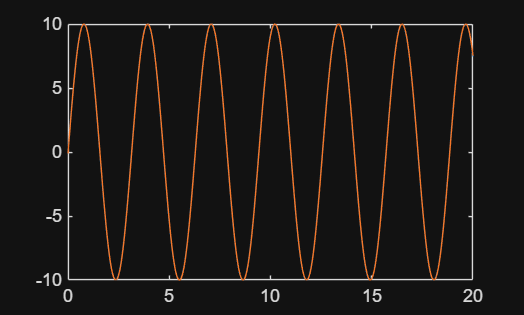

R = 10;
L = 1;
C = 512*10^-6;
t = [0:0.01:20];
u = 10 * sin(2*t);

num = [1];
den = [R*C 1];

[amp, f] = bode(num, den, 2);
y = 10*amp*sin(2*t + deg2rad(f));
plot(t,u,t,y)

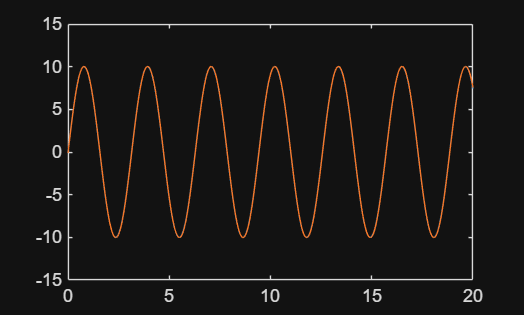


num = [1/(L*C)];
den = [1 R/L 1/(L*C)];

[amp, f] = bode(num, den, 2);
y = 10*amp*sin(2*t + deg2rad(f));
plot(t,u,t,y)